class_size = 30;
[X, y]=generate_data(class_size);

X =     2.5377    0.8884
    3.8339   -1.1471
   -0.2588   -1.0689
    2.8622   -0.8095
    2.3188   -2.9443
    0.6923    1.4384
    1.5664    0.3252
    2.3426   -0.7549
    5.5784    1.3703
    4.7694   -1.7115


X =    -3.0891   -1.1480
   -1.9674    0.1049
   -1.4475    0.7223
   -0.8994    2.5855
   -0.4558   -0.6669
   -1.9141    0.1873
   -3.4916   -0.0825
   -2.7423   -1.9330
   -3.0616   -0.4390
    0.3505   -1.7947


X =     2.9080    2.5201
    0.8252    1.9800
    1.3790    1.9652
   -1.0582    1.2018
   -0.4686    3.0187
   -0.2725    1.8668
    1.0984    1.2855
   -0.2779    3.3514
    0.7015    1.7752
   -2.0518    1.4110


X =    -1.3617   -2.5320
    0.4550   -0.3179
   -0.8487   -2.8757
   -0.3349   -2.4838
    0.5528   -2.7120
    1.0391   -3.1742
   -1.1176   -2.1922
    1.2607   -2.2741
    0.6601   -0.4699
   -0.0679   -2.2490


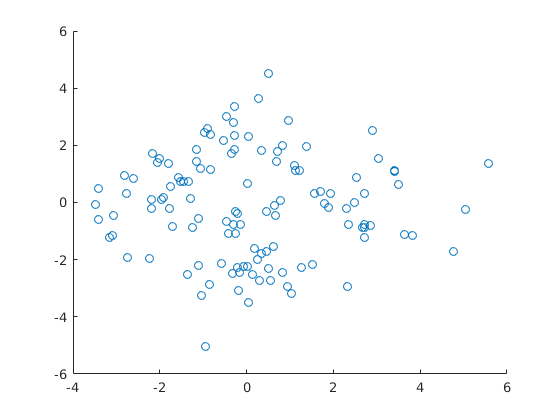

clf;
scatter(X(:,1),X(:,2));

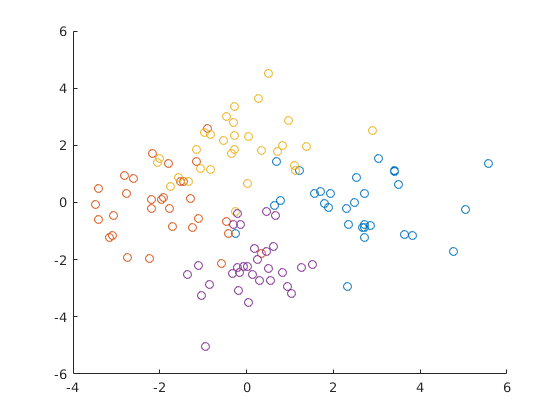

clf;
scatter(X(1:class_size,1), X(1:class_size,2))
hold on
scatter(X(class_size+1:class_size*2,1), X(class_size+1:class_size*2,2))
scatter(X(class_size*2+1:class_size*3,1), X(class_size*2+1:class_size*3,2))
scatter(X(class_size*3+1:class_size*4,1), X(class_size*3+1:class_size*4,2))

[X, y] = shuffle_data(X,y);

[X_train, y_train, X_test, y_test] = partition_data(X, y, 0.9)

X_train =     1.3790    1.9652
    0.7925    0.0774
   -0.8487   -2.8757
    1.6966    0.3714
    0.1352   -2.5078
   -1.3337    0.7429
    3.0347    1.5326
    1.0984    1.2855
    0.4550   -0.3179
   -1.8022    1.3546


y_train =      1     0
     0     1
     0     0
     0     1
     0     0
     1     0
     0     1
     1     0
     0     0
     1     1


X_test =     0.9642    2.8620
   -0.5807   -2.1384
    2.5377    0.8884
   -2.7423   -1.9330
   -0.9415   -5.0292
    3.4897    0.6277
   -3.1658   -1.2078
   -0.0679   -2.2490
   -2.2437   -1.9609
   -0.2620   -0.3299


y_test =      1     0
     1     1
     0     1
     1     1
     0     0
     0     1
     1     1
     0     0
     1     1
     1     0


net = perceptron();
net = configure(net, X_train', y_train');


Invalid expression. Check for missing multiplication operator, missing or unbalanced delimiters, or other syntax error. To construct matrices, use brackets instead of parentheses.

view(net)

net = train(net, X_train', y_train');

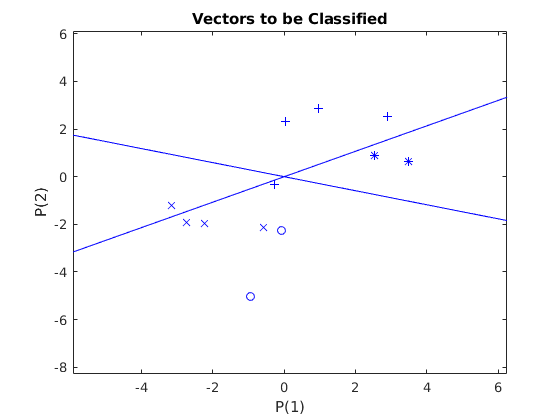

hiper_plot(net, X_test, y_test)

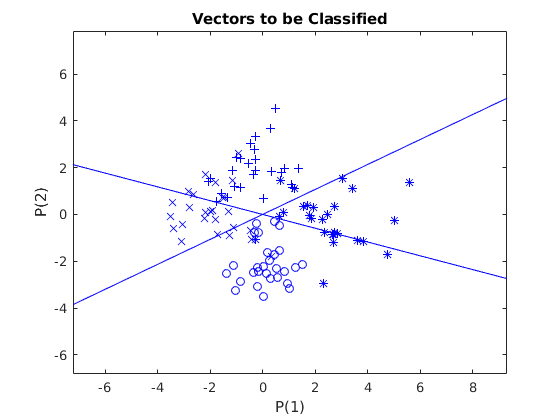

hiper_plot(net, X_train, y_train)

net.b{1}(1)

ans = 0

net.iw{1,1}

ans =    -2.2855    4.2828
    0.9527    3.2333
